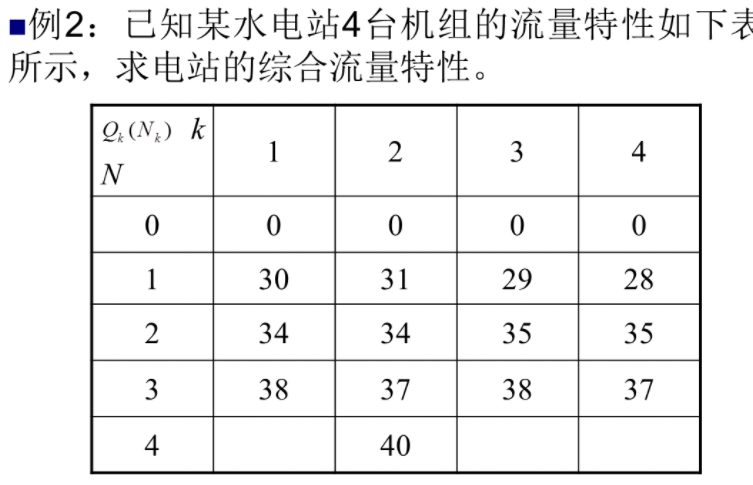

clc;clear
N_Q=[0 30 34 38 inf
    0 31 34 37 40
    0 29 35 38 inf
    0 28 35 37 inf];
N=13;
step_size=1;
[row,col]=size(N_Q);
N_Q=[N_Q,inf(row,N/step_size-col+1)];
[row,col]=size(N_Q);

stage=row;

choose=strings(row*2,col);
choose(1,:)=N_Q(1,:);
choose(2,:)=0:step_size:N;
count=3;

f=N_Q(1,:);
for i=2:stage
    f_next=zeros(col,1);
    for x=N:-step_size:0
        storage=zeros(x/step_size+1,1);
        for y=0:step_size:x
            storage(y/step_size+1)=N_Q(i,y/step_size+1)+f((x-y)/step_size+1);
        end

        temp_max=min(storage);
        temp_num=find(storage==temp_max)';
        choose(count,x/step_size+1)=num2str(temp_max);
        choose(count+1,x/step_size+1)=num2str((temp_num-1)*step_size);
        f_next(x/step_size+1)=temp_max;
    end
    count=count+2;
    f=f_next;
end

result_value=str2double(choose(row*2-1,col))

result_value = 153

MYFUN(N,step_size,row*2,col,choose);

road = 3

road = 3

road = 4

road = 3